# Kinematic DH Parameters for 3-link RPR arm

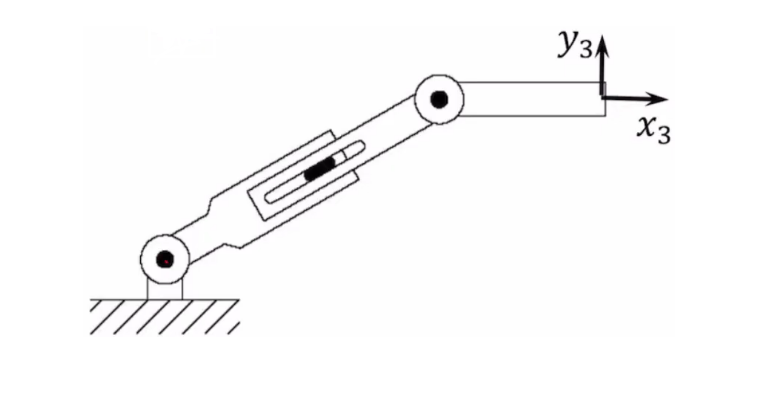

imshow(imread("./figures/RPR.png"))

### Robot Description

- **{r, p, r} : **r for revolute, p for prismatic

- **{0, 0, L_1} : **radius lenghts

- **{Pi/2, -Pi/2, 0} :** link twists

- **{0, q_2, 0} : **link offset rotation

- **{q1, 0, q3} : **joint rotation

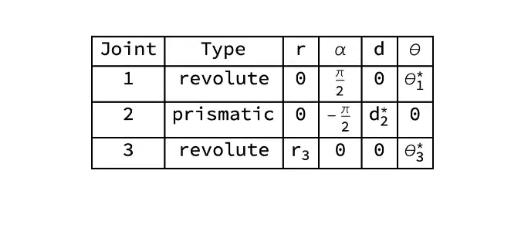

imshow(imread("./figures/DH.png"))

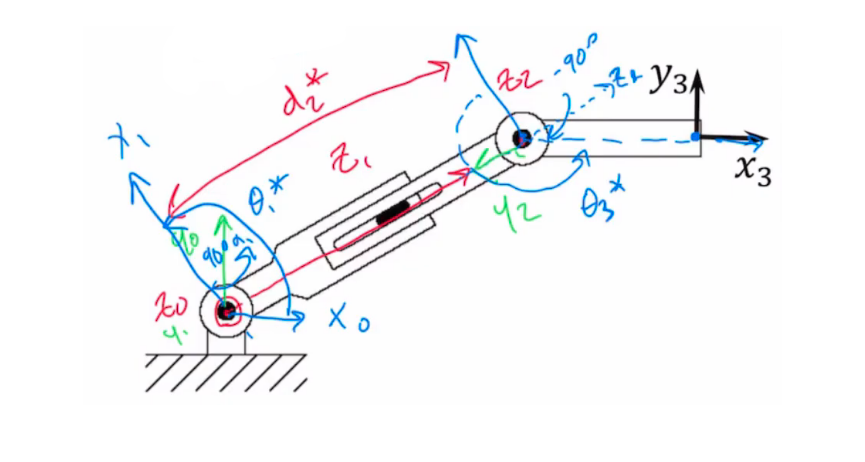

imshow(imread("./figures/annotated_RPR.png"))


$$A_i ={\mathrm{Rot}}_{z,\theta_i } {\mathrm{Trans}}_{z,d_i } {\mathrm{Trans}}_{x,\alpha_i } {\mathrm{Rot}}_{x,\alpha_i }$$



$$A_i =\left\lbrack \begin{array}{cccc}
c_{\theta_i }  & -s_{\theta_i }  & 0 & 0\\
s_{\theta_i }  & c_{\theta_i }  & 0 & 0\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack \;\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & 1 & 0 & 0\\
0 & 0 & 1 & d_i \\
0 & 0 & 0 & 1
\end{array}\right\rbrack \;\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & \alpha_i \\
0 & 1 & 0 & 0\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack \;\left\lbrack \begin{array}{cccc}
1 & \sqrt{}0 & 1 & 0\\
0 & c_{\alpha_i }  & -s_{\alpha_i }  & 0\\
0 & s_{\alpha_i }  & c_{\alpha_i }  & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$



$$A_i =\left\lbrack \begin{array}{cccc}
c_{\theta_i }  & -s_{\theta_i } c_{\alpha_i }  & s_{\theta_i } c_{\alpha_i }  & a_i c_{\theta_i } \\
s_{\theta_i }  & c_{\theta_i } c_{\alpha_i }  & -c_{\theta_i } s_{\alpha_i }  & a_i s_{\theta_i } \\
0 & s_{\alpha_i }  & c_{\alpha_i }  & d_i \\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$


imshow(imread("./figures/annotated_RPR.png"))

The DH parameters define the geometry of how each rigid body attaches to its parent via a joint. The parameters follow a four transformation convention:

- $A$ — Length of the common normal line between the two *z*-axes, which is perpendicular to both axes

- $\alpha$ — Angle of rotation for the common normal

- $d$ — Offset along the *z*-axis in the normal direction, from parent to child

- $\theta$ — Angle of rotation for the *x*-axis along the previous *z*-axis

Specify the parameters for the system as a matrix. Values come from .

clc
clear
close all

arms = [15.0071 24.9199 8 28];  
% arms(1) =  distance between lower pole and main pole on ground.
% arms(2) =  lower pole length.
% arms(3) =  distance between higher pole and the main pole on top surface.
% arms(4) =  top pole length.

tops = [50 90];             % top surface dimensions
main = 42;                  % main pole length
% main = 40;                % main pole length


min_height = 35;
top_pole_sep = 20;
sigma = rad2deg(atan(min_height/(min_height-top_pole_sep/2)));
gamma = rad2deg(atan(min_height/(min_height+top_pole_sep/2)));



%%

syms a b c alpha beta theta;

fcn = b^2 == a^2 + c^2 - 2*a*c*cos(beta);

S = solve(fcn, c);

S = simplify(S(2))

$$S = a\,\cos\left(\beta \right)+\sqrt{a^{2}\,{\cos\left(\beta \right)}^{2}-a^{2}+b^{2}}$$



%%

fcn2 = c == b/sin(beta)*sin(pi-beta-(asin(sin(beta)*a/b)));

S2 = solve(fcn2,c);

S2 = simplify(S2)

$$S2 = b\,\sqrt{-\frac{a^{2}\,{\sin\left(\beta \right)}^{2}-b^{2}}{b^{2}}}+a\,\cos\left(\beta \right)$$

syms t1 d2 Xe Ye ;

dhparams = [0   	 pi/2	    0   	t1 ;
            0	    -pi/2       d2      0  ;
            10	     0	        0	    pi-t1 ];


H0_1 = DH(dhparams(1,1), dhparams(1,2), dhparams(1,3), dhparams(1,4))

$$H0\_1 = \left(\begin{array}{cccc} \cos\left(t_{1}\right) & 0 & \sin\left(t_{1}\right) & 0\\ \sin\left(t_{1}\right) & 0 & -\cos\left(t_{1}\right) & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

H1_2 = DH(dhparams(2,1), dhparams(2,2), dhparams(2,3), dhparams(2,4))

$$H1\_2 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & -1 & 0 & d_{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

H2_3 = DH(dhparams(3,1), dhparams(3,2), dhparams(3,3), dhparams(3,4))

$$H2\_3 = \left(\begin{array}{cccc} -\cos\left(t_{1}\right) & -\sin\left(t_{1}\right) & 0 & -10\,\cos\left(t_{1}\right)\\ \sin\left(t_{1}\right) & -\cos\left(t_{1}\right) & 0 & 10\,\sin\left(t_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


H0_2 = H0_1*H1_2

$$H0\_2 = \left(\begin{array}{cccc} \cos\left(t_{1}\right) & -\sin\left(t_{1}\right) & 0 & d_{2}\,\sin\left(t_{1}\right)\\ \sin\left(t_{1}\right) & \cos\left(t_{1}\right) & 0 & -d_{2}\,\cos\left(t_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

H0_3 = H0_1*H1_2*H2_3

$$H0\_3 = \left(\begin{array}{cccc} -{\cos\left(t_{1}\right)}^{2}-{\sin\left(t_{1}\right)}^{2} & 0 & 0 & -10\,{\cos\left(t_{1}\right)}^{2}-10\,{\sin\left(t_{1}\right)}^{2}+d_{2}\,\sin\left(t_{1}\right)\\ 0 & -{\cos\left(t_{1}\right)}^{2}-{\sin\left(t_{1}\right)}^{2} & 0 & -d_{2}\,\cos\left(t_{1}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

O1_x = simplify(H0_1(1,4))

$$O1\_x = 0$$

O1_y = simplify(H0_1(2,4))

$$O1\_y = 0$$


O2_x = simplify(H0_2(1,4))

$$O2\_x = d_{2}\,\sin\left(t_{1}\right)$$

O2_y = simplify(H0_2(2,4))

$$O2\_y = -d_{2}\,\cos\left(t_{1}\right)$$


O3_x = simplify(H0_3(1,4))

$$O3\_x = d_{2}\,\sin\left(t_{1}\right)-10$$

O3_y = simplify(H0_3(2,4))

$$O3\_y = -d_{2}\,\cos\left(t_{1}\right)$$


xeq = Xe == O3_x

$$xeq = \mathrm{Xe}=d_{2}\,\sin\left(t_{1}\right)-10$$

yeq = Ye == O3_y

$$yeq = \mathrm{Ye}=-d_{2}\,\cos\left(t_{1}\right)$$


S = solve([xeq yeq],[t1 d2])

S = struct with fields:
    t1: [2×1 sym]
    d2: [2×1 sym]



simplify(S.t1)

$$ans = \left(\begin{array}{c} 2\,\mathrm{atan}\left(\frac{\mathrm{Ye}-\sqrt{{\mathrm{Xe}}^{2}+20\,\mathrm{Xe}+{\mathrm{Ye}}^{2}+100}}{\mathrm{Xe}+10}\right)\\ 2\,\mathrm{atan}\left(\frac{\mathrm{Ye}+\sqrt{{\mathrm{Xe}}^{2}+20\,\mathrm{Xe}+{\mathrm{Ye}}^{2}+100}}{\mathrm{Xe}+10}\right) \end{array}\right)$$

simplify(S.d2)

$$ans = \left(\begin{array}{c} -\sqrt{{\mathrm{Xe}}^{2}+20\,\mathrm{Xe}+{\mathrm{Ye}}^{2}+100}\\ \sqrt{{\mathrm{Xe}}^{2}+20\,\mathrm{Xe}+{\mathrm{Ye}}^{2}+100} \end{array}\right)$$


% these set the relation of x play and the height, to reduce the equation
% to single input


Xe = 35;
% Xe = main*sin(deg2rad(sigma)) ;
% Xe = 10 ;
% 38.2743
% -10
% 10
% -33.282

% S=subs(S,Ye,sqrt((sqrt((main*cos(deg2rad(sigma))+10)^2+(main*sin(deg2rad(sigma)))^2))^2-Xe^2))

S=subs(S,Ye,-1/175*Xe^2+42)

S = struct with fields:
    t1: [2×1 sym]
    d2: [2×1 sym]



% Ye = 48.47;

t_1 = simplify(S.t1);
d_2 = simplify(S.d2);

t_1(2)

$$ans = 2\,\mathrm{atan}\left(\frac{\sqrt{{\mathrm{Xe}}^{2}+20\,\mathrm{Xe}+1325}+35}{\mathrm{Xe}+10}\right)$$

d_2(2)

$$ans = \sqrt{{\mathrm{Xe}}^{2}+20\,\mathrm{Xe}+1325}$$



t_1 = eval(t_1)

t_1 =    -0.9098
    2.2318


d_2 = eval(d_2)

d_2 =   -57.0088
   57.0088


t_3 = -pi + t_1

t_3 =    -4.0513
   -0.9098



O1_x = simplify(H0_1(1,4));
O1_y = simplify(H0_1(2,4));

O2_x = simplify(H0_2(1,4));
O2_y = simplify(H0_2(2,4));

O3_x = simplify(H0_3(1,4));
O3_y = simplify(H0_3(2,4));

% t1 = deg2rad(180-104.511+90)
% t3 = deg2rad(90-(180-104.511))
% d2 = sqrt(20^2+30^2)


t1 = t_1(2)

t1 = 2.2318

d2 = d_2(2)

d2 = 57.0088



d1 = triIneq(arms(1),arms(2),(t1-pi/2))

d1 = 35.0000

d2

d2 = 57.0088

d3 = triIneq(arms(3),arms(4),pi-t1-pi/2)

d3 = 33.8807

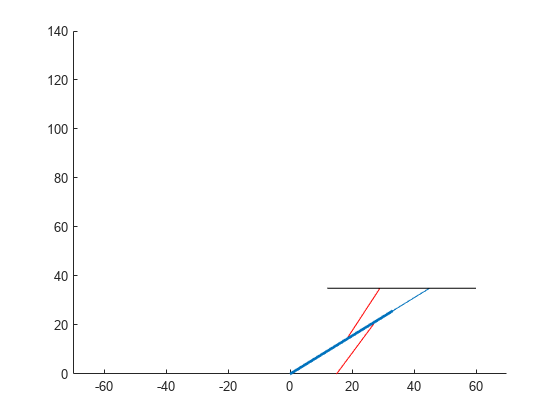




O2_x = eval(O2_x);
O2_y = eval(O2_y);

O3_x = eval(O3_x);
O3_y = eval(O3_y);

clf
link1 = line([0,O1_x],[0,O1_y]);
link2 = line([O1_x, O2_x],[O1_y, O2_y]);
link3 = line([O2_x, O3_x],[O2_y, O3_y]);
arm1 = line([arms(1),d1*cos(t1-pi/2) ],[0,d1*sin(t1-pi/2) ], 'color','red');
arm2 = line([O2_x-(2*arms(3)),O2_x-d3*cos(pi-t1-pi/2) ],[O2_y,O2_y+d3*sin(pi-t1-pi/2) ], 'color','red');
top = line([O2_x,O2_x+15],[O2_y,O2_y ], 'color','black');
top2 = line([ O2_x,O2_x-(tops(1)-(2*arms(3)))/2-(2*arms(3))],[O2_y,O2_y ], 'color','black');
middle = line([0, main*cos(t1-pi/2)],[0, main*sin(t1-pi/2)], 'LineWidth', 2);

xlim([-70 70])
ylim([0 140])


d1 = d1

d1 = 35.0000

d3 = d2-d3

d3 = 23.1281

d2 = d2-main

d2 = 15.0088

function [A] = DH(a,alpha,d,theta)

A = [cos(theta) -sin(theta)*round(cos(alpha))  sin(theta)*round(sin(alpha)) a*cos(theta);
     sin(theta)  cos(theta)*round(cos(alpha)) -cos(theta)*round(sin(alpha)) a*sin(theta);
     0           round(sin(alpha))             round(cos(alpha))            d ;
     0           0                             0                            1];
end

function [c] = triIneq(a,b,beta)
c = b*(-(a^2*sin(beta)^2 - b^2)/b^2)^(1/2) + a*cos(beta);
end